# Notebook 10: Matched Filter Detection Simulations

This notebook will be on the simulations that will be used to calculate the probability of detection for signals just like notebook number 9. This will be used to generate data that will be used in the results section of my thesis.

% --Setup
    clear; clc; format compact; close all;
    cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Parameters
    num_sims = 100;  % [CHANGE THIS TO CHANGE THE DETECTION RESOLUTION]
    alphas = 4:-0.1:3;

    W_SNRs = [];
    B_SNRs = [];
    W_detection = [];
    B_detection = [];

% --Simulation loop
    for i = 1:length(alphas)

        % --Loop Setup
            alpha = alphas(i);
            X_W = [];
            X_B = [];
            W_Det = [];
            B_Det = [];

        for j = 1:num_sims

            % --Create signal and find SNR
                [white_signal, brown_signal, reference, ref_chirp_long, time] = generate_signals(alpha, alpha);
                
                noise = white_signal - ref_chirp_long;
                noise_power = sum(noise.^2)/(2*length(noise) + 1);
                signal_power = sum(reference.^2)/(2*length(reference) + 1);
                W_SNR = 10*log10(signal_power/noise_power);

                noise = brown_signal - ref_chirp_long;
                noise_power = sum(noise.^2)/(2*length(noise) + 1);
                B_SNR = 10*log10(signal_power/noise_power);

                % --Location of signal start
                    [~, location_start] = findpeaks(ref_chirp_long, "NPeaks",1);

            % --Save SNR values
                X_W = [X_W, W_SNR];
                X_B = [X_B, B_SNR];

            % --Matched Filtering
                ref_flip = conj(fliplr(reference'));
            
                white_matched = filter(ref_flip, 1, white_signal);
                white_matched_mean = mean(abs(white_matched));
                threshold_white = max(white_matched) - 1.5*white_matched_mean;
            
                % --Max value of the matched filter
                    [Iw,Jw] = find(white_matched == max(white_matched));
            
                brown_matched = filter(ref_flip, 1, brown_signal);
                brown_matched_mean = mean(abs(brown_matched));
                threshold_brown = max(brown_matched) - 1.5*brown_matched_mean;
            
                % --Max value of matched filter output
                    [Ib,Jb] = find(brown_matched == max(brown_matched));
                
            % --Detection criteria for white noise detection
                [peaks, index] = findpeaks(white_matched, 'MinPeakHeight', threshold_white, 'MinPeakDistance',100);
                peak = [peaks; 
                        index];
                max_peak = max(peaks);
                [~, J] = find(peak == max_peak);

                if abs(peak(2,J) - 55001) <= 50
                    WD = 1;
                else
                    WD = 0;
                end

            % --Detection criteria for brown noise detection
                [peaks, index] = findpeaks(brown_matched, 'MinPeakHeight', threshold_brown, 'MinPeakDistance',100);
                peak = [peaks; 
                        index];
                max_peak = max(peaks);
                [~, J] = find(peak == max_peak);
            
                if abs(peak(2,J) - 55001) <= 50
                    BD = 1;
                else
                    BD = 0;
                end

            % --Save Data
                W_Det = [W_Det, WD];
                B_Det = [B_Det, BD];

        end

        % --Average out values
            A = mean(X_W);
            B = mean(X_B);

            W_SNRs = [W_SNRs, A];
            B_SNRs = [B_SNRs, B];

            A = mean(W_Det);
            B = mean(B_Det);
            
            W_detection = [W_detection, A];
            B_detection = [B_detection, B];
            
    end


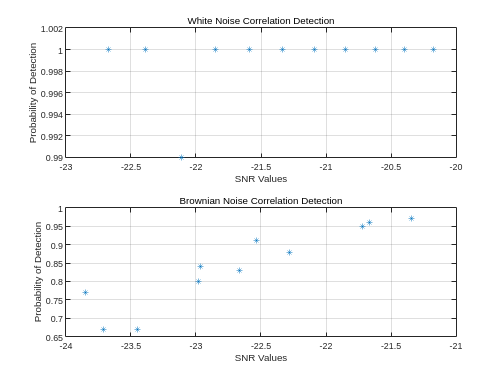

% --Plotting out Detection Data and Saving them
    figure()
    subplot(2,1,1)
    plot(W_SNRs, W_detection, "*")
        hold on
        grid on
        xlabel("SNR Values")
        ylabel("Probability of Detection")
        subtitle("White Noise Correlation Detection")

    subplot(2,1,2)
    plot(B_SNRs, B_detection, "*")
        hold on
        grid on
        xlabel("SNR Values")
        ylabel("Probability of Detection")
        subtitle("Brownian Noise Correlation Detection")

## Save Data File

% --Saving Data
    cd("/home/samkramer/Desktop")
    save("Matched_Sim_7.mat","B_SNRs","B_detection", "W_detection","W_SNRs")